# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable lgraph_MobileNet.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 29-Apr-2021 13:50:43

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph_MobileNet = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([100 100 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","Conv1","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","bn_Conv1","Epsilon",0.001)
    clippedReluLayer(6,"Name","Conv1_relu")
    groupedConvolution2dLayer([3 3],1,32,"Name","expanded_conv_depthwise","Padding","same")
    batchNormalizationLayer("Name","expanded_conv_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","expanded_conv_depthwise_relu")
    convolution2dLayer([1 1],16,"Name","expanded_conv_project","Padding","same")
    batchNormalizationLayer("Name","expanded_conv_project_BN","Epsilon",0.001)
    convolution2dLayer([1 1],96,"Name","block_1_expand","Padding","same")
    batchNormalizationLayer("Name","block_1_expand_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_1_expand_relu")
    groupedConvolution2dLayer([3 3],1,96,"Name","block_1_depthwise","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","block_1_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_1_depthwise_relu")
    convolution2dLayer([1 1],24,"Name","block_1_project","Padding","same")
    batchNormalizationLayer("Name","block_1_project_BN","Epsilon",0.001)];
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","block_2_expand","Padding","same")
    batchNormalizationLayer("Name","block_2_expand_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_2_expand_relu")
    groupedConvolution2dLayer([3 3],1,144,"Name","block_2_depthwise","Padding","same")
    batchNormalizationLayer("Name","block_2_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_2_depthwise_relu")
    convolution2dLayer([1 1],24,"Name","block_2_project","Padding","same")
    batchNormalizationLayer("Name","block_2_project_BN","Epsilon",0.001)];
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = [
    additionLayer(2,"Name","block_2_add")
    convolution2dLayer([1 1],144,"Name","block_3_expand","Padding","same")
    batchNormalizationLayer("Name","block_3_expand_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_3_expand_relu")
    groupedConvolution2dLayer([3 3],1,144,"Name","block_3_depthwise","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","block_3_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_3_depthwise_relu")
    convolution2dLayer([1 1],32,"Name","block_3_project","Padding","same")
    batchNormalizationLayer("Name","block_3_project_BN","Epsilon",0.001)];
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","block_4_expand","Padding","same")
    batchNormalizationLayer("Name","block_4_expand_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_4_expand_relu")
    groupedConvolution2dLayer([3 3],1,192,"Name","block_4_depthwise","Padding","same")
    batchNormalizationLayer("Name","block_4_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_4_depthwise_relu")
    convolution2dLayer([1 1],32,"Name","block_4_project","Padding","same")
    batchNormalizationLayer("Name","block_4_project_BN","Epsilon",0.001)];
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = additionLayer(2,"Name","block_4_add");
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","block_5_expand","Padding","same")
    batchNormalizationLayer("Name","block_5_expand_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_5_expand_relu")
    groupedConvolution2dLayer([3 3],1,192,"Name","block_5_depthwise","Padding","same")
    batchNormalizationLayer("Name","block_5_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_5_depthwise_relu")
    convolution2dLayer([1 1],32,"Name","block_5_project","Padding","same")
    batchNormalizationLayer("Name","block_5_project_BN","Epsilon",0.001)];
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = [
    additionLayer(2,"Name","block_5_add")
    convolution2dLayer([1 1],192,"Name","block_6_expand","Padding","same")
    batchNormalizationLayer("Name","block_6_expand_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_6_expand_relu")
    groupedConvolution2dLayer([3 3],1,192,"Name","block_6_depthwise","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","block_6_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_6_depthwise_relu")
    convolution2dLayer([1 1],64,"Name","block_6_project","Padding","same")
    batchNormalizationLayer("Name","block_6_project_BN","Epsilon",0.001)];
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","block_7_expand","Padding","same")
    batchNormalizationLayer("Name","block_7_expand_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_7_expand_relu")
    groupedConvolution2dLayer([3 3],1,384,"Name","block_7_depthwise","Padding","same")
    batchNormalizationLayer("Name","block_7_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_7_depthwise_relu")
    convolution2dLayer([1 1],64,"Name","block_7_project","Padding","same")
    batchNormalizationLayer("Name","block_7_project_BN","Epsilon",0.001)];
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = additionLayer(2,"Name","block_7_add");
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","block_8_expand","Padding","same")
    batchNormalizationLayer("Name","block_8_expand_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_8_expand_relu")
    groupedConvolution2dLayer([3 3],1,384,"Name","block_8_depthwise","Padding","same")
    batchNormalizationLayer("Name","block_8_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_8_depthwise_relu")
    convolution2dLayer([1 1],64,"Name","block_8_project","Padding","same")
    batchNormalizationLayer("Name","block_8_project_BN","Epsilon",0.001)];
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = additionLayer(2,"Name","block_8_add");
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","block_9_expand","Padding","same")
    batchNormalizationLayer("Name","block_9_expand_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_9_expand_relu")
    groupedConvolution2dLayer([3 3],1,384,"Name","block_9_depthwise","Padding","same")
    batchNormalizationLayer("Name","block_9_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_9_depthwise_relu")
    convolution2dLayer([1 1],64,"Name","block_9_project","Padding","same")
    batchNormalizationLayer("Name","block_9_project_BN","Epsilon",0.001)];
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = [
    additionLayer(2,"Name","block_9_add")
    convolution2dLayer([1 1],384,"Name","block_10_expand","Padding","same")
    batchNormalizationLayer("Name","block_10_expand_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_10_expand_relu")
    groupedConvolution2dLayer([3 3],1,384,"Name","block_10_depthwise","Padding","same")
    batchNormalizationLayer("Name","block_10_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_10_depthwise_relu")
    convolution2dLayer([1 1],96,"Name","block_10_project","Padding","same")
    batchNormalizationLayer("Name","block_10_project_BN","Epsilon",0.001)];
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],576,"Name","block_11_expand","Padding","same")
    batchNormalizationLayer("Name","block_11_expand_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_11_expand_relu")
    groupedConvolution2dLayer([3 3],1,576,"Name","block_11_depthwise","Padding","same")
    batchNormalizationLayer("Name","block_11_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_11_depthwise_relu")
    convolution2dLayer([1 1],96,"Name","block_11_project","Padding","same")
    batchNormalizationLayer("Name","block_11_project_BN","Epsilon",0.001)];
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = additionLayer(2,"Name","block_11_add");
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],576,"Name","block_12_expand","Padding","same")
    batchNormalizationLayer("Name","block_12_expand_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_12_expand_relu")
    groupedConvolution2dLayer([3 3],1,576,"Name","block_12_depthwise","Padding","same")
    batchNormalizationLayer("Name","block_12_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_12_depthwise_relu")
    convolution2dLayer([1 1],96,"Name","block_12_project","Padding","same")
    batchNormalizationLayer("Name","block_12_project_BN","Epsilon",0.001)];
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = [
    additionLayer(2,"Name","block_12_add")
    convolution2dLayer([1 1],576,"Name","block_13_expand","Padding","same")
    batchNormalizationLayer("Name","block_13_expand_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_13_expand_relu")
    groupedConvolution2dLayer([3 3],1,576,"Name","block_13_depthwise","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","block_13_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_13_depthwise_relu")
    convolution2dLayer([1 1],160,"Name","block_13_project","Padding","same")
    batchNormalizationLayer("Name","block_13_project_BN","Epsilon",0.001)];
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],960,"Name","block_14_expand","Padding","same")
    batchNormalizationLayer("Name","block_14_expand_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_14_expand_relu")
    groupedConvolution2dLayer([3 3],1,960,"Name","block_14_depthwise","Padding","same")
    batchNormalizationLayer("Name","block_14_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_14_depthwise_relu")
    convolution2dLayer([1 1],160,"Name","block_14_project","Padding","same")
    batchNormalizationLayer("Name","block_14_project_BN","Epsilon",0.001)];
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = additionLayer(2,"Name","block_14_add");
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],960,"Name","block_15_expand","Padding","same")
    batchNormalizationLayer("Name","block_15_expand_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_15_expand_relu")
    groupedConvolution2dLayer([3 3],1,960,"Name","block_15_depthwise","Padding","same")
    batchNormalizationLayer("Name","block_15_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_15_depthwise_relu")
    convolution2dLayer([1 1],160,"Name","block_15_project","Padding","same")
    batchNormalizationLayer("Name","block_15_project_BN","Epsilon",0.001)];
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

tempLayers = [
    additionLayer(2,"Name","block_15_add")
    convolution2dLayer([1 1],960,"Name","block_16_expand","Padding","same")
    batchNormalizationLayer("Name","block_16_expand_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_16_expand_relu")
    groupedConvolution2dLayer([3 3],1,960,"Name","block_16_depthwise","Padding","same")
    batchNormalizationLayer("Name","block_16_depthwise_BN","Epsilon",0.001)
    clippedReluLayer(6,"Name","block_16_depthwise_relu")
    convolution2dLayer([1 1],320,"Name","block_16_project","Padding","same")
    batchNormalizationLayer("Name","block_16_project_BN","Epsilon",0.001)
    convolution2dLayer([1 1],1280,"Name","Conv_1")
    batchNormalizationLayer("Name","Conv_1_bn","Epsilon",0.001)
    clippedReluLayer(6,"Name","out_relu")
    globalAveragePooling2dLayer("Name","global_average_pooling2d_1")
    fullyConnectedLayer(3,"Name","fc")
    softmaxLayer("Name","Logits_softmax")
    classificationLayer("Name","classoutput")];
lgraph_MobileNet = addLayers(lgraph_MobileNet,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_1_project_BN","block_2_expand");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_1_project_BN","block_2_add/in2");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_2_project_BN","block_2_add/in1");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_3_project_BN","block_4_expand");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_3_project_BN","block_4_add/in2");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_4_project_BN","block_4_add/in1");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_4_add","block_5_expand");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_4_add","block_5_add/in2");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_5_project_BN","block_5_add/in1");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_6_project_BN","block_7_expand");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_6_project_BN","block_7_add/in2");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_7_project_BN","block_7_add/in1");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_7_add","block_8_expand");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_7_add","block_8_add/in2");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_8_project_BN","block_8_add/in1");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_8_add","block_9_expand");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_8_add","block_9_add/in2");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_9_project_BN","block_9_add/in1");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_10_project_BN","block_11_expand");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_10_project_BN","block_11_add/in2");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_11_project_BN","block_11_add/in1");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_11_add","block_12_expand");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_11_add","block_12_add/in2");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_12_project_BN","block_12_add/in1");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_13_project_BN","block_14_expand");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_13_project_BN","block_14_add/in2");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_14_project_BN","block_14_add/in1");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_14_add","block_15_expand");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_14_add","block_15_add/in2");
lgraph_MobileNet = connectLayers(lgraph_MobileNet,"block_15_project_BN","block_15_add/in1");

## Plot Layers

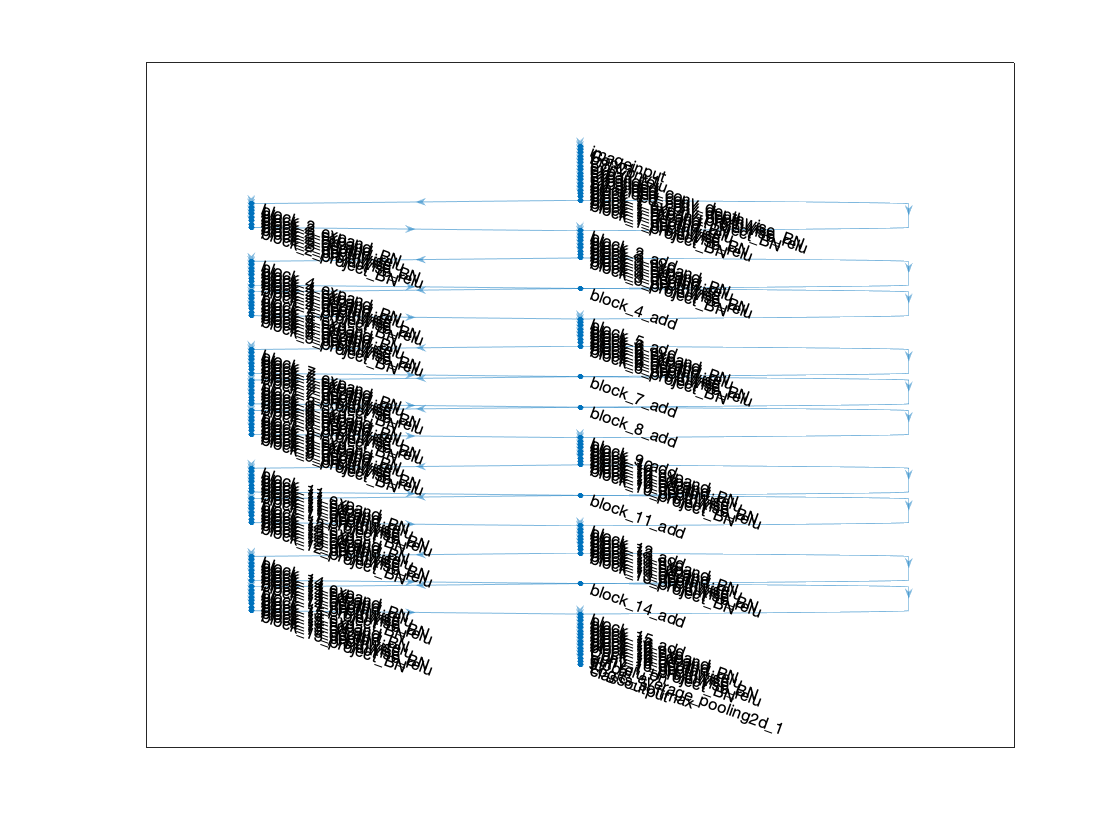

plot(lgraph_MobileNet);